wb=0.105948%-5.66E-4

wb = 0.1059

wcp= 0.014145;% 0.044145; 
wm=0.030411; 
d1=130.75e-3

d1 = 0.1308

d2=50.75e-3

d2 = 0.0508


e=41.91e-3; % Offset centro de masa 

I=5.8e-5; 

Coeficiente = wcp*d2-wm*d1-wb*e

Coeficiente = -0.0077

thetap = 0; 
correccion = 0.5; 
k=0.0694%0.0177%0.1008154434*correccion

k = 0.0694

Gamma = 1.25;%0.816685;%0.85
b=Gamma*2*I

b = 1.4500e-04

s=tf('s');
c = (((wcp*d2-wm*d1-wb*e)/I)*(-cosd(thetap)));
G=((d1)/I)/((s^2)+(b/I)*s+(((wcp*d2-wm*d1-wb*e)/I)*(-cosd(thetap))))

G =
 
         2254
  -------------------
  s^2 + 2.5 s + 132.7
 
Continuous-time transfer function.



pole(G)

ans =   -1.2500 +11.4531i
  -1.2500 -11.4531i


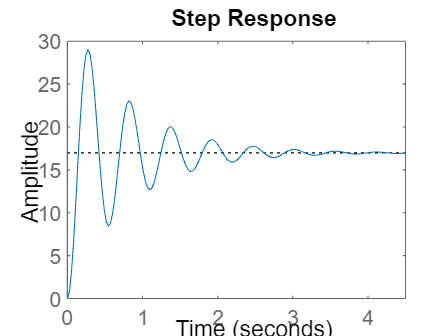


step(G)

Gnum = cell2mat(G.Numerator)

Gnum = 1.0e+03 *

         0         0    2.2543


Gden = cell2mat(G.Denominator)

Gden =     1.0000    2.5000  132.7355


pwm=0.5

pwm = 0.5000

timeR = 0.4

timeR = 0.4000


[Gm Pm Wcg Wcp] = margin(G)

Gm = Inf

Pm = 3.1036

Wcg = Inf

Wcp = 48.8259

Gm = 20*log10(Gm)

Gm = Inf


PWM_INPUT = 10; 
MAX_PWM = 80; 
DZ = 3; 
sim("plantaV1.slx")

No system or file called 'plantaV1.slx' found.